# Funtzioak

Tutorial honetan ikusiko dugu $\mathbb R^d$-n nola egin lan Matlaben bidez. Zehatz mehatz ikasiko dugu nola Matlabekin limiteak eta deribatuak kalkulatu, eta nola egin funtzioen grafikoak Matlaben bidez. 

clear all %Ezabatzeko lehen zegoena. Oso gomendagarria da programak lerro honekin hastea.

## 3D grafoak

Hasteko, ikusiko dugu funtzio bat nola irudikatu. Adibidez, $x^2-y^2$ funtzioa. Grafo baten gainazala irudikatzeko fsurf komandoa erabili behar da. 

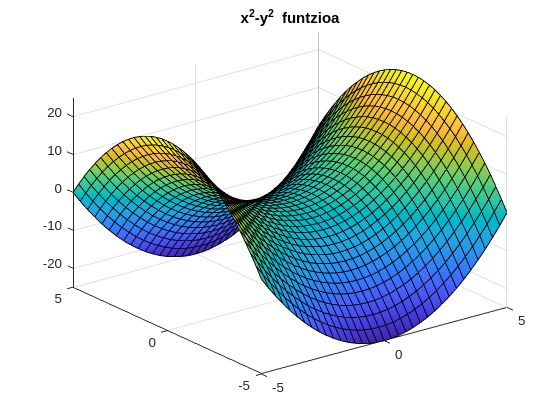

hyperbol= @(x,y) x.^2-y.^2;%Aldagai sinbolikoekin egin daiteke
fsurf(hyperbol)
title('x^2-y^2 funtzioa')%Izenburua jartzeko grafoari
grid on

Defektuz, ezer esaten ez badiogu $[-5,5]^2$-n irudikatzen dizu funtzioak.  Ikusteko **fsurf** dituen aukerak guztiak irakurri dokumentazioa.

## Grafiko baten sestra kurbak

Ikus dezagun orain grafiko baten sestra-kurbak nola egin. Horretarako **fcontour** agindua erabili behar da. 

grafo=fcontour(hyperbol)%Honek lerroak egiten ditu bakarrik. 

grafo =   FunctionContour with properties:

     Function: @(x,y)x.^2-y.^2
    LineColor: 'flat'
    LineStyle: '-'
    LineWidth: 0.5000
         Fill: off
    LevelList: [-20 -15 -10 -5 0 5 10 15 20 25]

  Show all properties


Grafo baten propietateak Matlaben erakusten ditu. **Show all properties** klikatuz, ikus ditzakezue propietate guztiak. Propietate horien balioak alda ditzakegu grafo ostean puntu bat jarri eta gero balio berriak. Adibidez, lerroen lodiera itzu ez geratzeko:

grafo.LineWidth= 2.5;
grafo.MeshDensity= 200;%Lerroen kalitatea handitzeko
grafo.LevelList= -20:2:20 %Honekin hautatzen da zeren kurbak nahi ditugun. 

grafo =   FunctionContour with properties:

     Function: @(x,y)x.^2-y.^2
    LineColor: 'flat'
    LineStyle: '-'
    LineWidth: 2.5000
         Fill: off
    LevelList: [-20 -18 -16 -14 -12 -10 -8 -6 -4 -2 0 2 4 6 8 10 12 14 16 18 20]

  Show all properties


Gogoratu -20:2:20 direla -20 hasita 2 batuz 20 izatera arte lortutako balioen bektorea. Ikusi LevelList. 

Beste balio zer egiten duten ikusteko irakur ditzakezue dokumentazioa edo alda ditzakezue Ohartu kurbak $y=\pm x$-ra konbergitzen dutela. Logikoa.

Azkenik, ikusteko lerroak zer esan nahi duten **colorbar** idatzi behar da fcontouren ostean. Ez da beharrazkoa gauza biak egitea; nahiz eta hemen egiten dugun osotasunagatik.

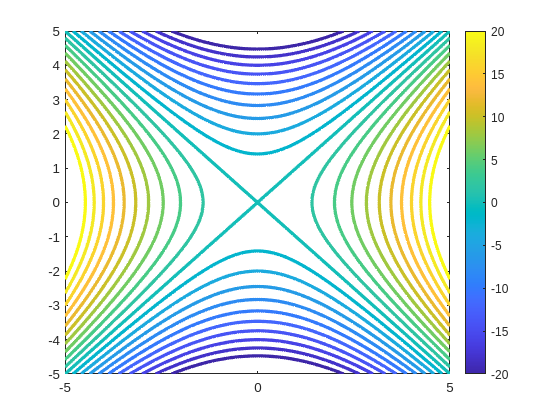

colorbar

## Domeinuak Matlaben bidez irudikatzen. Sarrera

Matbal erabil daiteke funtzio batzuen existentzia eremeua irudikatzeko; hain zuzen ere haurretik ikusitako instrukzioak erabiliz. Adibidez, ikus dezagun $\sqrt{16-x^2-y^2}$ nola irudika dezakegu. Hasteko, honetarako aldagai sinbolikoak behar ditugu. 

syms r x y 

Esan daiteke aldi berean bi aldagai sinbolikoak direla. Kontuz, ez idatzi **syms xy** . Kasu horretan aldagai sinboliko bakarra deklaratuko du.

Gainazalak marrazteko fsurf erabili behar da, planuan ere: 

fsurf(x,sqrt(r-x^2),0, [0 16 -4 4], "EdgeColor", 'none', 'Meshdensity',50)

Behin baldintza horiekin, esan behar zaio x, y aldagaiak irudikatzeko. Izan ere fsurf ere balio du $(f_1(x,y),f_2(x,y),f_3(x,y))$ motako gainazalak irudikatzeko. $f_3$ ostean dauden lau zenbakizko bektoreak da nondik nora doan lehenengo eta bigarren aldagai sinbolikoak kontuan izanik aldagai sinbolikoak alfabetikoki ordenatuta daudela. Ikusi nahi baduzu ordena idatzi **syms** komando lehioan.  "**EdgeColor**", '**none**' balio du defektuz marrazten dituen $x$ eta $y$ ardatzei paralelo diren lerroen irudien kolorea aldatzeko, eta 'none' jarriz gero zuzenean ez ditu marraztuko. **Mesh density** da presizioa handitzeko. Defektuz 35 da. Noski, zenbat eta zehaztasun gehiago, orduan eta denbora gehiago beharko du. 

hold on 
fsurf(x,-sqrt(4-x^2),0, [0 16 -4 4], "EdgeColor", 'none','Meshdensity',50)
view(2) %planoa irudikatzeko.
axis equal 

Ardatzak tamaina berbera izateko, baina kontuz, batzutan eskalako irudiek ez dute laguntzen. Agindu hau idatzi behar da grafo guztien ostean. Fijatzen bazarete lehenengo biak definitzean arazoak dugu 0-ren inguruan. Arrazoia da hor y-ren deribatu partziala z-rekiko infinitu bihurtzen dela, eta horrek arazo konputazioanal sortzen ditu: zehaztasuna galtzen da. Zorionez, erraz konpon daiteke. 

fsurf(sqrt(r-y^2),y,0,  [0 16 -4 4], "EdgeColor", 'none', 'Meshdensity',50)
fsurf(-sqrt(r-y^2),y,0,  [0 16 -4 4], "EdgeColor", 'none', 'Meshdensity',50)

Azkenik, singulartasun bat dugu jatorria, hori ere erraz konpon daiteke, eremua ezagutuz: 

fsurf(x,y, 0,[-2 2], "EdgeColor", 'none')

Kasu honetan, bi aldagiak irudikatuko ditu -2tik 2ra.

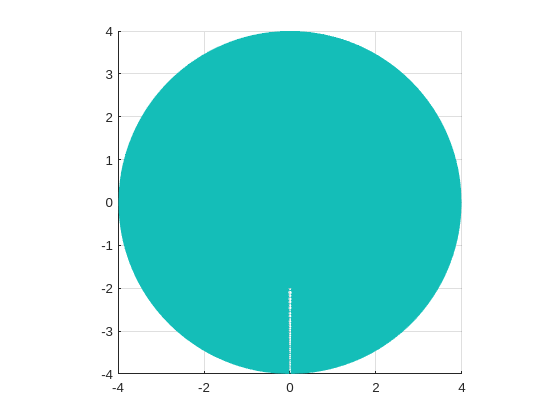

hold off

clear x y r

## Domeinuak marrazteko beste erak

Noski, aurrekoa apur bat txapuzeroa izan da. Arazoa baldin bada gradientea infinitu egiten dela, bila daitezke arazo hori konpontzeko beste erak: 

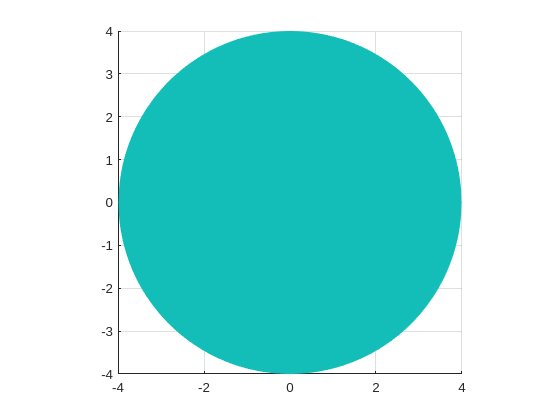

syms r x
fsurf(x,sqrt(r^2-x^2),0, [-4 4], "EdgeColor", 'none', 'Meshdensity',50)
hold on
fsurf(x,-sqrt(r^2-x^2),0, [-4 4], "EdgeColor", 'none','Meshdensity',50)
hold off
view(2)
axis equal

Ikusten. Batzuetan hobe da pentsatzea. Eta, hain zuzen ere, gauza hauengatik oso gomendagarria da jakitea Matlab barnetik nola funtzionatzen duen eta zer arazo sor daitezkeen. Azkenengo aukera bat polarretan idaztea da; hots $(r\cos(\theta),r\sin(\theta),0)$ idaztea, baina aukera hori egitura berezietarako balio du soilik. 

clear x r

## Limiteak eta Matlab (ii)

Atal honetan ikusiko dugu nola erabili Matlab limiteak kalkulatzeko. Horretarako, pakete sinbolikoa erabili behar da. Lehenengo aukera beti da irudikatzea. Adibidez,

f1=@(x,y) x*y/sqrt(x^2+y^2)

f1 = function_handle with value:
    @(x,y)x*y/sqrt(x^2+y^2)


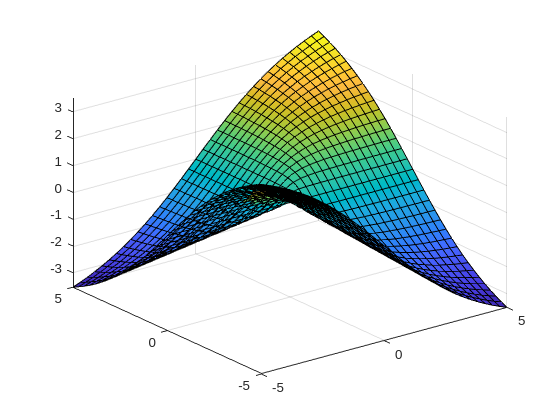

fsurf(f1) %Grafikoa begiratuz argi dago funtzioa jarraitua bihur daitekeela 

$0$-n balioa nulua harturik, hori izango delako limitea. Noski, hori frogatu behar da gero. Ikus dezagun zer  gertatzen den limitea ez duen beste funtzio batekin

f2=@(x,y) x*y/(x^2+y^2)

f2 = function_handle with value:
    @(x,y)x*y/(x^2+y^2)


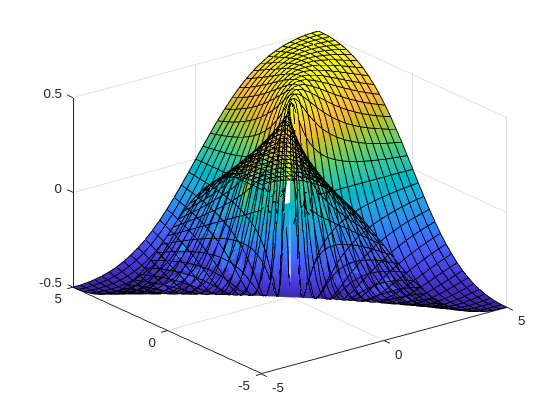

fsurf(f2)

Hemen ikusten da lerro zuri bat jatorrian. Argi dago grafoa ikusita funtzioa ez dela jarraitua jatorrian; baina noski, hori gero probatu behar da. 

Lor dezagun orain limitea Matlab komando baten bidez. Matlaben ez dago pakete zuzenik aldagai anitzetako funtzioen limiteak kalkulatzen dituena. Aitzitik, hoberena da polarrera pasatzea limite horiek kalkulatzeko, eta ikustea zer gertzen den $R\to 0$. Aitzitik, honekin ikusiko dugu zer geratzen den norabide limiteekin, baina ez dugu emaitzik lortuko limite globalari buruz. Demagun $\frac{xy}{\sqrt{x^2+y^2}}$  funtzioaren limitea kalkulatu nahi dugula. Orduan, honako hau kalkulatu beharko genuke:

syms R s
f1pol =@ (r,l) r*r*cos(l)*sin(l)/r;
limit(f1pol(R,s),R,0)

$$ans = 0$$

%Ikusten denez $0$ balioa berrezkuratzen dugu; hots, norabide limite guztiak existitzen dira eta limite horiek nulua dira. Hortaz, kandidatu bakarra dago. Aitzitik $xy/(x^2+y^2)$ funtzioaren limitea kalkulatzen ari bagara emaitza $s$-ren menpekoa izango da: 

f2pol =@ (r,l) r*r*cos(l)*sin(l)/(r^2);
limit(f2pol(R,s),R,0)

$$ans = \cos\left(s\right)\,\sin\left(s\right)$$

Hortaz, kosenuaren angeluarekiko menpekoa denez, limitea ezin da existitu. Era berean, **inf** edo **NaN** motako balio bat lortuz gero ere esan nahi du funtzioak ez duela limite errealik. Atal honekin bukatzeko, ikus dezagun zer gertatzen den $\frac{xy^2}{x^2+y^4}$ funtzioarekin. Teorian ikusi dugu limiterik ez duela.

limit((R^3*cos(s)*(sin(s))^2)/(R^2*(cos(s))^2+R^4*(sin(s))^4),R,0)

$$ans = 0$$

Ohartu, begin aldagaiak sinbolikoak deklaratu, ez da beharrezkoa @ notazioa erabilitzea funtzioa definitzeko. Funtzio horretan ematen du balioa $0$ dela. Honekin, kontuz ibili behar gara, egin duguna da norabide limiteak kalkulatu eta limite hori $s$-ren menpe adierazi, baina ez limite globala kalkulatu.

clear R s

## Matlab eta deribatuen kalkulua:

Ikus dezagun orain nola kalkulatu deribatuak pakete sinbolikoarekin. Imajinatu $\ln(1+x+y)$ funtzioaren deribatuak kalkulatu nahi ditugula. Horretarako pakete sinbolikoa erabil dezakegu, eta gradient komandoa. 

syms x y

gradient(log(1+x+y))%Matlaben logaritmo neperianoa log bezala idazten da. 

$$ans = \left(\begin{array}{c} \frac{1}{x+y+1}\\ \frac{1}{x+y+1} \end{array}\right)$$

Ikusten den bezala, oso era eraginkor batean kalkulatzen digu gradientea. Edonla ere, deribaturak banan banan kalkula ditzakegu, adibidez:

diff(log(1+x+y),x)%Horrela eskatzen da lehenengo ordeneko deribatu partziala ateratzeko

$$ans = \frac{1}{x+y+1}$$

diff(log(1+x+y),y)

$$ans = \frac{1}{x+y+1}$$

diff(log(1+x+y),x,x)%Bigarren ordeneko deribatuak x-rekiko

$$ans = -\frac{1}{{\left(x+y+1\right)}^{2}}$$

diff(log(1+x+y),x,y)%Hasteko x-rekiko egiten du, eta gero y-rekiko

$$ans = -\frac{1}{{\left(x+y+1\right)}^{2}}$$

diff(log(1+x+y),y,x)%Kontrako ordena

$$ans = -\frac{1}{{\left(x+y+1\right)}^{2}}$$

diff(log(1+x+y),y,y)

$$ans = -\frac{1}{{\left(x+y+1\right)}^{2}}$$

Gainera, hau erabili daiteke funtzio baten jakobiarra kalkulatzeko:

fvecadb= [log(1+x+y); x*y];

Gogoratu, puntu eta koma batekin bektore errenkada lor daiteke Matlaben. 

Jacfadb=[diff(fvecadb,x),  diff(fvecadb,y)]

$$Jacfadb = \left(\begin{array}{cc} \frac{1}{x+y+1} & \frac{1}{x+y+1}\\ y & x \end{array}\right)$$

Matlaben Matrizeak honela eraikitzen dira: zutabeetako balioak emanda. Bestalde, Matlaben deribatuak, eta adierazpen sinboliko bat orokorrean, ebalua daitezke. Adibidez, aurreko funtzioaren Jakobiarra kalkulatu nahi badugu $(1,0)$ puntuan. Horretarako **subs** funtzioa erabili behar dugu

subs(Jacfadb,[x,y],[1,0])

$$ans = \left(\begin{array}{cc} \frac{1}{2} & \frac{1}{2}\\ 0 & 1 \end{array}\right)$$

**subs** erabiltzeko idatzi behar da adierazpen sinbolikoak, ebaluatzen ari garen aldagaien bektorea, eta hartzen duten balioen bektorea. Ikusten denez, edozein adierazpen sinbolikoarekin erabil daiteke. Ere erabil daiteke bigarren ordeneko deribatuak kalkulatzeko, adibidez: 

subs(diff(log(1+x+y),x,x),[x,y],[0,0])

$$ans = -1$$

Azkenik, Matlaben kalkulu sinbolikoa erabil daiteke Taylorren segidak kalkulatzeko. Zehatz mehatz, **taylor(f,var,a)** jarri behar da, non **f **adierazpen sinbolikoa, var aldagaien bekotrea, **a** zentratzen dugun puntuan, etc.** a**-n ez badugu ezer jartzen, programak $(0,0)$ puntua hartuko du.    Gainera, '**order**' jar dezakegu Taylorren zer orde nahi dugun adierazteko  bestela, 5 ordeneko Taylorren seriea itzuliko baituzu. Kontuz, idatzi behar da hurbilpenaren maila gehi bat; adibidez:

taylor(log(1+x+y), [x y], 'order',2)%Lehen ordeneko hurbilpena

$$ans = x+y$$

taylor(log(1+x+y), [x y], 'order',3)%Bigarren ordeneko hurbilpena. 

$$ans = -\frac{x^{2}}{2}-x\,y+x-\frac{y^{2}}{2}+y$$

taylor(log(1+x+y), [x y], [1,1],'order',2)%Taylorren seriea [1,1] puntuan zentratuta

$$ans = \frac{x}{3}+\frac{y}{3}+\log\left(3\right)-\frac{2}{3}$$

Zenbakiko balioak behar izatekotan, **subs** funtzioa dugu,  ez ahaztu.

Bide batez, Matlab adierazpena sinplikatzen du; hori ekiditzeko, nahikoa da aldagai aldaketa bat egitea, izan ere  subs zenbakiekin ordezkatzeaz gain beste aldagai zinboliko batekin ordezka dezakegu

syms x2 y2
subs(taylor(log(1+x+y), [x y], [1,1],'order',2), [x,y], [x2+1,y2+1])

$$ans = \frac{x_{2}}{3}+\frac{y_{2}}{3}+\log\left(3\right)$$

Hortaz, x2-ren tokian idatzi beharko genuke x-1, eta y2ren tokian y2-1. Hori Taylorren seriea puntuan zentratuta zein den jakin nahi badugu, bestela, eragiketak egiteko Matlab lortatuko adierazpena ondo dago. 

clear x y x2 y2

## Funtzioen grafikoa eta planu ukitzailea.

Eraiki dezagun orain funtzio baten grafoa, plano tangentea, eta norabidezko deribatua adierazten duen bektorea. Hasteko, kontuan izan behar dugu bariable sinbolikoak dagoena erraz irudika daiteke **fsurf**, **fcontour**, eta motako horretako funtzio guztiekin. Izan ere, aldagai sinbolikoek idazkera beste aukera bat da. Irudika dezagun $x^2+4y^2$ eta planu tangentea $(1,1)$ puntua eta norabide deribatua $(4/5,3,4)$ norabidea

syms x y
fsurf(x^2+4*y^2, "FaceAlpha", 0.5)

Funtzioaren grafoa. FaceAlpha funtzioaren gardetasuna neurtzen du. Balio du gero beste zeozer irudikatzen badugu ondo ikusteko.

Nahi izatekotan 'EdgeColor' 'none' idatz daiteke  funtzioan $(t,x)$ eta $(t,y)$ motako kurbarik ez agertzeko, baina lerro horiek, nahiz eta politak ez izan, esaten dizute zer gertatzen den x eta y aldagaietan mugitzen zarenean

hold on %Bi grafo baino gehiago irudikatzeko
fsurf(taylor(x^2+4*y^2,[x, y], [1,1],'order', 2),'blue',"EdgeColor",'none')

Plano ukitzailea $(1,1,5)$ puntuan. Honela ikusten da planua nola ikutzen duen. Ohartu zenbat eta zoom gehiago egiten dugun orduan eta antz gehiago dute planu ukitzailea eta funtzioa.  Irudika dezagun orain kurba. Kurbak irudikatzeko fplot3 erabili behar da.

syms t % t aldagaia sinbolikotzat hartuko dugu. Horretarako, kurba 
%adiderazteko x eta y aldagaiak t-rekiko adtzen duten balioengatik
%ordezkatuko ditugu. 
kurba= subs([x,y,x^2+4*y^2],[x,y],[1+4/5*t,1+3/5*t])% Kurbaren osagaiak 

$$kurba = \left(\begin{array}{ccc} \frac{4\,t}{5}+1 & \frac{3\,t}{5}+1 & 4\,{\left(\frac{3\,t}{5}+1\right)}^{2}+{\left(\frac{4\,t}{5}+1\right)}^{2} \end{array}\right)$$

%subs laguntzarekin
fplot3(kurba(1),kurba(2),kurba(3), [-10,10], 'LineWidth',10,'color',  'black')

Beltzez irudikatzen dugu ondo ikusteko. Bai, gainazaletan ez da 'color' idatzi behar, baina kurbetan eta puntuetan bai. $[-10,10]$ da nondik nora hartzen ditugun $t$ balioak. Ikusten duzuenez, **fplot3** ez du funtzio bektorial bat edo adierazpen bektorial sinboliko bat eskatzen. Aitzitik, hiru funtzio eskalar edo adierazpen sinboliko eskalar behar ditu. 

zuzen= taylor(kurba,t,'order',2); %Zuzen ukitzailea puntuaren inguran.
fplot3(zuzen(1),zuzen(2),zuzen(3),[-10,10]  ,'LineWidth',10, 'color', 'magenta')

Ikusi dezakezuenez, zuzen ukitzailea planu ukitzailean dago. Hori plano ukitzailearen ondorio matematiko bat da: puntu horretan pasatzen diren kurben dinamikoen zuzen ukitzaileak osatzen duten planoa da. Azken, marraz dezagun tangentzia puntua ondo ikusteko:

plot3(1,1,5,".","Markersize",80, "color", "red") 

**Markersize** balio du puntuaren tamaina adierazteko, eta "." puntua borobila eta betea idazteko. Dauden aukera guztiak jakiteko, begiratu Matlaben dokumentazioa.

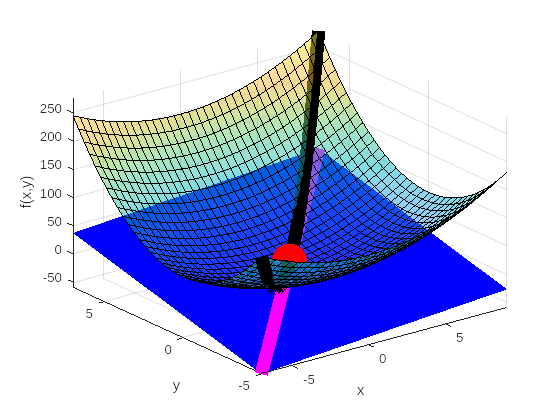

xlabel('x')%xlabel balio du x ardatzari x izena jartzeko. Oso lagungarria 
%izan daiteke 3D grafikoak biratzeko orduan.
ylabel('y')%Berdina y ardatzarekin
zlabel('f(x,y)')%berdina z ardatzarekin. Ohartu edozer idatz 
%dezakegula komila artean doan bitartean. 
hold off %Grafo berri bat hasteko .
%Behin grafoa izanda, exporta dezagun pdf bat bezala. 
Sizegcf= get(gcf, 'PaperPosition');
set(gcf, 'PaperSize', [Sizegcf(3) Sizegcf(4)]); %Lehenengo bi agianduak 
%balio dute grafoa tamaina handi batekin ateratzeko. Erabilgarria izan
%daiteke powerpoint batean jarri nahi baduzue. 
saveas(gcf, 'Ukitzaileak', 'pdf') %Irudia gordetzeko pdf bat bezala. 

Kontuz, begiratu zein den "current folder", hor gordeko baitu.

## Grafoa puntu baten ingurunean.

Zentra gaitezke puntu baten ingurune batean Adibidez, $\frac{1}{2x^2+y^2+1}$ funtzioaren plano ukitzailea kalkulatu nahi badugu $(1,0,1/3)$ puntuaren inguruan: 

syms x y
fsurf(1/(2*x^2+y^2+1),[0,2,-1,1], "FaceAlpha",0.5)

Bektorearen lehenengo bi balioak da nondik nora doa agertzen den lehenengo aldagai sinbolikoa, eta azkenengo biak bigarrena. Bi osagaiko bektorea jarriz gero balio bereberak hartuko ditu $x$-rako eta $y$-rako

xlabel('x')%xlabel balio du x ardatzari x izena jartzeko. Oso lagungarria 
%izan daiteke 3D grafikoak biratzeko orduan.
ylabel('y')%Berdina y ardatzarekin
zlabel('Funtzioaren balioa')%berdina z ardatzarekin. Ohartu edozer idatz 
%dezakegula komila artean doan bitartean. 
hold on 
fsurf(taylor(1/(2*x^2+y^2+1),[x y], [1,0], 'order',2),[0,2,-1,1],'blue')

Azkenik, irudikatuko dugu planu ukitzailea. Ondo ezberdintzeko, gorriz irudikatuko dugu. Erabil daiteke beste edozein kolore. Ikusi nahi badituzu zein koloreak zaren begiratu fsurf-en Matlaben dokumentazioa. Hemen utzi dugu lerroak adierazteko planoarekin dagokion funtzioa osohurbil dagoela. 

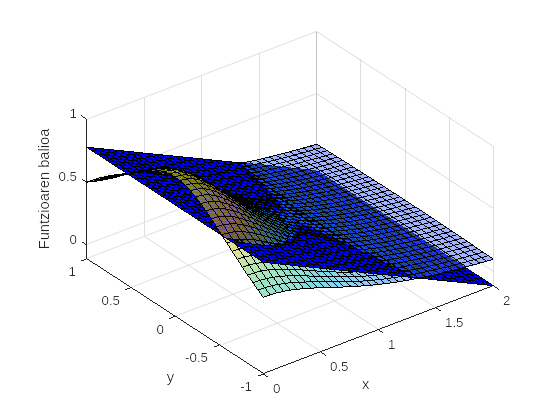

hold off
axis equal

Ikusi nahi badugu irudia benetako eskalan axis equal erabili behar da, bestela irudi distorsinatu bat izango dugu. Batzutan, noski, ez du merezi hau egitea; adibidez, aurreko irudian. 

clear x y

## Plano ukatzailea detaile gehiago

Badirudi plano ukitzailea zeharkatzen duela. Ikus dezagun zer gertatzen den detaile gehiagorekin: 

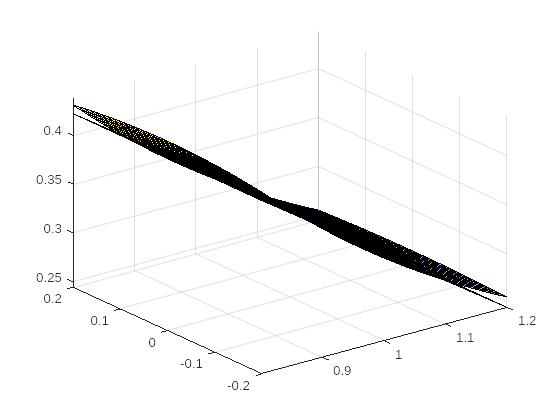

syms x y
fsurf(1/(2*x^2+y^2+1),[0.8,1.2,-0.2,0.2], "FaceAlpha",0.5)%Bektorearen lehenengo bi balioak da nondik 
hold on
fsurf(taylor(1/(2*x^2+y^2+1),[x y], [1,0], 'order',2),[0.8,1.2,-0.2,0.2],'blue')
hold off

Hemen ikusten denez, oso ondo hurbiltzen du. Kontua da ez duela zentzu klasikoan, baizik eta zeharatzen duela. Normala da, kontuan izanik gainazalekin zuzenekin baino egoera gehiago daudela. Edonola ere, fijatu oso ondo hurbiltzen duela. 

clear x y